# **Gas Humidifier Model (Benchmark)**

clear variables 
close all
clc

**Test Data by Solsona et al. (Figures 4 to 6), taken from **[https://doi.org/10.1016/j.enconman.2017.01.036](https://doi.org/10.1016/j.enconman.2017.01.036)

Air temperature at humidifier outlet:

t_TAir_Sol = [0;63;252;641;1197;1607;2091;2627;3373;4077;4854;5968];
TAir_Sol = [27.3;27.3;29.6;37.7;49.4;58.1;64.4;69.1;72;73;73.5;73.4];

Relative humidity of air at humidifier outlet:

t_RH_Sol = [31;279;445;621;632;1066;1688;2650;3458;3996;4928;5964];
RH_Sol = [200;198.7;159;131.2;119;107;98.5;90.8;88.6;87.3;87.4;87.2];

Air pressure at humidifier outlet:

t_P5_Sol = [0;941;1924;2775;3610;4314;4879;5558;5959];
P5_Sol = [108627;109020;109804;110784;111569;111765;111765;111569;111569];

## **Simulation**

Total time of simulation:

Simulation_time = 6000; % [s]
Step = 0.01; % [s]
Iterations = ceil(Simulation_time/Step);

### Corrections

Mass transfer coefficient:

CorrecK_MT = 0.795; 

Volumetric flow rate of air:

CorrecFlowRate = 1.1;

Fraction of heat lost to the surroundings:

CorrecQLost = 0.23;

Height fraction of shell filled with liquid water:

FracFilled = 0.8;

Pressure produced by the compressor over the atmospheric Pressure:

CorrecPCompres = 0.925 + 0.00432;

Heater loss of the last section of pipe:

CorrecQHeaterAir = 0.7;

Control action of the heater in the final section:

Control_action_2 = 0.15;

### General parameters

Acceleration due to gravity:

g = 9.8; % [m/s2]

Universal gas constant:

R = 8.31441; % [kJ/kmol K] o  [Pa m3/mol K] o  [kPa m3/kmol K]

Air molar mass:

MM_Air = 29; % [kg/kmol]

Water molar mass:

MM_Vapor = 18; % [kg/kmol]

Absolute roughness of the stainless steel tube (**Steel**):

RoughSteel = 45e-6; % [m]  

Absolute roughness of Teflon (polytetrafluoroethylene) hose (**Tefl**):

RoughTefl = 1.5e-6; % [m]  

Barcelona atmospheric pressure:

PAtm = 101325; % [Pa]

Heat capacity of liquid water at average humidifier temperature:

Cp_w_liq = 4.184; % [kJ/(Kg-K)]

Heat of vaporization of water at average humidifier temperature:

LambdaVap = 2360; % [kJ/kg]

Heat transferred by the electric heater of the humidifier (**Heater 1**):

Qdot_Heater1 = 123/1000; % [kJ/s]

Heat lost through conduction and to the surroundings:

QLost = CorrecQLost*Qdot_Heater1; % [kJ/s]

Density of liquid water at 60°C to evaluate the mass of water in the humidifier:

Rho_Water_60 = 983; % [kg/m3]

Heat transferred by the tube heater in the last section (**Heater 2**):

Qdot_Heater2 = CorrecQHeaterAir*5/1000; % [kJ/s]

Heat transfer coefficient from the tubes to the air inside the tubes:

hAir = 50/1000; % [units]

### Parameters for calculating fluid properties

Antoine's equation constants for water vapor pressure:

A = 16.5362; 
B = 3985.44;
C = -38.9974;

Constants for the Irving and Liley dry air viscosity equation:

MA0 = -9.8601e-1;
MA1 = 9.080125e-2;
MA2 = -1.17635575e-4;
MA3 = 1.2349703e-7;
MA4 = -5.7971299e-11;

Constants for the viscosity of water vapor:

MV0 = 8.058131868e1;
MV1 = 4.000549451e-1;

### Operation data

Known pressures at points marked between circles on the PFD (Process Fow Diagram):

Pressure at the compressor outlet, taken as the discharge pressure, which must be adjusted with the calculations of the rest of the sections:

P0(1) = CorrecPCompres*156483; % [Pa]

Initial pressure at point 1 on the PFD. An estimated value is placed, which is taken from the last successful simulation. As it is a function of the flow rate, it should be adjusted with this parameter. A constant value is used here:

P1_EstimaIni = 139540; % [Pa]  

Humidity and temperature conditions of the inlet atmospheric air:

Relative humidity in Barcelona, given by Solsona 2017:

RHAmb_Porc = 60; % [%]

Relative humidity in its fraction equivalence:

RHAmb(1)= RHAmb_Porc/100; 

Temperature, taken from Fig. 4 of the Solsona paper:

TAmb = 27 + 273.15; % [K]

Relative humidity at humidifier outlet at startup:

RH5(1) = RHAmb(1); % The device starts full of air

Relative humidity at the exit of the entire assembly (entrance to the cell) at startup:

RH6(1) = RHAmb(1); % The device starts full of air

Temperature at the compressor outlet:

T0 = TAmb; % [K] 
% Temperature increase due to compression is negligible

Initial value of the temperature at the humidifier outlet:

T5(1) = T0; % [K] It is assumed equal to the compressor outlet or point 0.

Gas temperature at the exit of the entire assembly (entrance to the cell) at startup:

T6(1) = T0; % [K]

Temperature of the liquid water contained in the humidifier at startup:

T8(1) = T0; % [K]

Liquid water temperature at humidifier inlet:

T_InLiqWater = 20 + 273.15; % [K]

Relative heights of the points in the assembly. The points marked with circles on the PFD. All distances are measured from the floor of the assembly box:

Height of the compressor discharge:

z0 = 0.20; % [m]

 Height of the mixing Tee:

z1 = 0.08; % [m]

Height of the Tee that is before the filter. It's right on the floor of the assembly box:

z2 = 0; % [m]

Height of change from steel tube to Teflon hose:

z3 = 0.02; % [m]

Height of the air at the humidifier inlet:

z4 = 0.175; % [m]

 Height at the humidifier outlet, assumed lower on the assembly floor:

z5 = 0; % [m]

Height of the fuel cell entrance, assumed to be on the assembly floor:

z6 = 0; % [m]

**Parameters for friction losses**

Parameters K1 and K Infinite of the 2K method. Valid for all sections since they are universal values of the method that only depend on the type of connection between the fittings:

Standard welded 90° elbows:

K1_90 = 800; % Standard, Flanged - welded
Kinf_90 = 0.25; % Standard, Flanged - welded

Standard welded 45° elbows:

K1_45 = 500; % Standard, Flanged - welded
Kinf_45 = 0.2; % Standard, Flanged - welded

Flanges considered as flow-through Tee unions:

K1_Union = 150; % run-trhough tee: Flanged - welded
Kinf_Union = 0.5; % run-trhough tee: Flanged - welded

Tee as standard welded 90° elbow:

K1_90_Tee = 800; % Standard, Flanged - welded
Kinf_90_Tee = 0.8; % Standard, Flanged - welded

Valve coefficient:


$$\Delta P = Specific\;gravity\times\left(\frac{Q}{kvs}\right)^{2}, \;\;\;\;Q\;in\;[m^{3}/h]\;\;\;\;and\;\;\;\;\Delta P\;in\;[bar=101\;kPa]$$


It will be assumed that the specific gravity is 1.0, that is, the density of the mixture is very similar to that of air at these conditions.

kvs = 1.75; % [m3/h]

Common values and calculations for Teflon (**Tefl**) and Stainless Steel (**Steel**) hose lines:

Diameter and flow area of Teflon (**Tefl**) hose with nominal diameter 4.0 mm:

DTefl_inches = 4.0/25.4; % [in]
DTefl_cm = DTefl_inches*2.54; % [cm]
DTefl = DTefl_cm/100; % [m]
ATefl = pi*(DTefl^2)/4; % [m2]

Diameter and flow area of stainless steel hose (**Steel**) with nominal diameter 4.25 mm:

Dsteel_inches = 4.25/25.4; % [in]
Dsteel_cm = Dsteel_inches*2.54; % [cm]
Dsteel = Dsteel_cm/100; % [m]
Asteel = pi*(Dsteel^2)/4; % [m2]

Stainless steel section between points 0 and 1 (**Steel01**):

(All fittings are in stainless steel)

Total length of the **Steel01 **section with constant diameter:

L_Steel01 = 0.14; % [m]

Volume of humid air contained in this section (which, since there is no change in diameter, is equal to the total volume, without considering the volume contained in the fittings, it is left as an error because it is small):

V_Steel01 = Asteel*L_Steel01; % [m3]

Teflon section between points 1 and 2 (**Tefl12**):

(All fittings are in stainless steel)

Total length of the **Tefl12 **section with constant diameter:

L_Tefl12 = 1.05; % [m]

Volume of humid air contained in this section (under the same assumption of the previous section):

V_Tefl12 = ATefl*L_Tefl12; % [m3]

Stainless steel section between points 2 and 3 (**Steel23**):

(All fittings are in stainless steel)

Total length of the **Steel23 **section with constant diameter:

L_Steel23 = 0.14+0.09+0.06+0.05+0.06+0.04+0.06+0.28+0.02+0.05+0.24; % [m]

Volume of humid air contained in this section (under the same assumption of the previous section):

V_Steel23 = Asteel*L_Steel23; % [m3]

Teflon section between points 3 and 4 (**Tefl34**):

(All fittings are in stainless steel)

Total length of the **Tefl34 **section with constant diameter:

L_Tefl34 = 0.45 + 0.95; % [m]

Volume of humid air contained in this section (under the same assumption of the previous section):

V_Tefl34 = ATefl*L_Tefl34; % [m3]

**NOTE: **between points 4 and 5 is the humidifier, whose pressure drop is calculated using the data provided by the manufacturer of that equipment, see below.

Teflon section between points 5 and 6 (**Tefl56**):

(All fittings are in stainless steel)

Total length of the **Tefl56 **section with constant diameter:

L_Tefl56 = 0.63; % [m]

Volume of humid air contained in this section (under the same assumption of the previous section):

V_Tefl56 = ATefl*L_Tefl56; % [m3]

Volumetric flow rate of air measured under normal conditions, as delivered by the flowmeter: NL are Normal Liters:

VdotN_Measured = CorrecFlowRate*5.0; % [NL/min] measured in each test, 5.0 is an intermediate value

Normal cubic meter (Nm3) - Temperature: 0 °C, Pressure: 1.01325 barA

Standard cubic meter (Sm3) - Temperature: 20 °C, Pressure: 1.01325 barA

To convert to laboratory conditions, apply:

Q1 = (T1/T2)*(P2/P1)*Q2, flow rate in NL/min corrected to the ambient conditions of the laboratory. Note that it is calculated with the pressure at Point 1:

Vdot_Amb_L_min = (TAmb/273.15)*(P1_EstimaIni/PAtm)*VdotN_Measured; % [L/min]

Conversion to [m3/s]:

Vdot_Amb = Vdot_Amb_L_min*(1/1000)*(1/60); % [m3/s] 

Conversion to mass flow:

Vapor pressure of water at ambient laboratory conditions with Antoine's equation:

PVaporAmb = 1000*exp(A - (B/(TAmb+C))); 

Mole fraction of water vapor at the saturation point measured at ambient conditions:

y_sat_Amb = PVaporAmb/PAtm;

Mole fraction of water vapor at atmospheric air conditions:

y_Amb = y_sat_Amb*RHAmb(1);

Sets the initial value at startup:

y_6(1) = y_Amb;

Note that mole fractions are used even though all balances are made in mass units. This is because the relationship between mole fractions and partial pressures is direct.

Calculation of Density mixture of Dry Air (DA) and Water Vapor (WV) at ambient laboratory conditions:

Rhomix_Amb = (0.001*PAtm/(R*TAmb))*MM_Air*(1 - y_Amb*(1 - (MM_Vapor/MM_Air))); % [kg/m3]

(Remember that the R units of gases require compensation by (1/1000) to use pressure in Pa and the mass in mole and not in kmol)

Molar mass of the mixture at ambient laboratory conditions:

MM_mixAmb = y_Amb*MM_Vapor + (1 - y_Amb)*MM_Air; % [kg/kmol]

Air mass flow measured at atmospheric inlet humidity conditions:

mdotmix_Amb = Vdot_Amb*Rhomix_Amb; % [kg/s]

Set the mole fraction of water vapor at the humidifier outlet to the inlet mole fraction at the initial instant, assuming that the entire system is full of atmospheric air at startup:

y_5(1) = y_Amb;

Conversion of mole fraction of water vapor to mass fraction:

w_5(1) = y_5(1)*(MM_Vapor/MM_mixAmb);

Concentration of water in the membrane at the water side. This parameter is critical for tuning. Values: 14 to 22:

Dry membrane density:

RhoMem_Dry = 0.002*1000*1000; % [kg/m3] originally given in [kg/cm3]

Molar mass of dry membrane:

MM_Mem_Dry = 1100; % [kg/kmol]

Alpha for Water. The constant value taken from literature by Solsona et al. is 22, too high for operating condition. We take that of Chen et al., who experimentally adjust to this value:

AlphaW = 15.6;

Molar volumetric concentration of water in membrane at water side:

CW_MemW_cte = (RhoMem_Dry/MM_Mem_Dry)*AlphaW;

Parameter associated with the activation energy of the water molecule (Solsona et al. 2017):

E0 = 7378; % [kJ/kmol]

Dimensions of the Nafion tubes and the humidifier shell:

Internal diameter of a Nafion tube, for air flow:

D_Int_TubeNafion = 0.00132; % [m] From Cheng, Li and Peng

Membrane thickness of each Nafion tube:

Average value: Solsona uses 0.0127 cm = 127 um in the simulator. Chen, Li and Pen give 140 um.

Thickness_Mem_Nafion = 133.5/1000000; % microns converted to [m]

Average value of internal-external diameters to calculate average mass transfer area:

D_Avg_TubeNafion=D_Int_TubeNafion+Thickness_Mem_Nafion;

Total height of the humidifier shell:

L_ShellHumid = 0.175; % [m] equals (z4-z5)

Effective height for mass transfer through the Nafion tubes, which is assumed equal to 90% of the total height of the cylinder:

L_Efec_TubeNafion = FracFilled*L_ShellHumid; % [m]

Data and calculations related to the Nafion tubes inside the humidifier:

Number of Nafion tubes in the humidifier:

(If in 25mm (491mm2 Area) of shell Chen et al. accommodate 60 tubes, how many tubes can be accommodated in a shell of 103.4mm (8937mm2). There will be 17 times that number of tubes, that is, 1026 tubes. We will assume 5 times just to equal the heat transfer area reported by Solsona in his work = 0.2 m2)

NumTubesNafion = 1100;

Area for total mass and heat transfer adding all the Nafion tubes. It is assumed equal to the surface area:

A_Mem = NumTubesNafion*( pi*D_Avg_TubeNafion*L_Efec_TubeNafion ); % [m2]

Heat transfer area of the Nafion tubes, which is assumed to be the surface area and therefore equal to the mass transfer area:

A_H_Tubes = A_Mem; % [m2] according to Solsona is about 0.2 m2

Internal flow area for air in a Nafion tube:

A_IntFlowOneTubeNafion = pi*((D_Int_TubeNafion^2)/4); % [m2]

Internal volume of a Nafion tube:

V_OneTubeNafion = A_IntFlowOneTubeNafion*L_Efec_TubeNafion; % [m3]

Total volume of humid air contained in all Nafion tubes:

V_mixHumidifier = V_OneTubeNafion*NumTubesNafion; % [m3]

Initial mass of humid air contained in the Nafion tubes:

M_PS_V(1) = V_mixHumidifier*Rhomix_Amb; % [kg]

External diameter of a Nafion tube:

(For volume occupied by the tubes):

D_Ext_TubeNafion = D_Int_TubeNafion + (2*Thickness_Mem_Nafion); % [m]

Projected (external) area of a Nafion tube:

A_ProjExtOneTubeNafion = pi*((D_Ext_TubeNafion^2)/4);  % [m2]

Total (external) volume occupied by a Nafion tube up to the liquid level, since it is considered that the shell is not 100% full of liquid:

V_ExtOneTubeNafion = A_ProjExtOneTubeNafion*L_Efec_TubeNafion;  %[m3]

Total volume occupied by the Nafion tubes in the humidifier:

V_ExtTubesNafion = V_ExtOneTubeNafion*NumTubesNafion; % [m3] 

Area compensation to calculate the volume of water inside the cylinder:

Diameter of the cylinder that acts as the humidifier shell:

D_Cylinder = 0.95*0.1034; % [m] Penalized by wall thickness

Flow area of the cylindrical humidifier shell, assuming that the given diameter is the internal:

A_FlowCylinder = (pi*D_Cylinder^2)/4; % [m2]

Total volume or capacity of the humidifier shell:

Vol_ShellHumid = A_FlowCylinder*L_Efec_TubeNafion; % [m3]

Maximum liquid water volume inside the shell:

Vol_WaterMaxShellHumid = Vol_ShellHumid - V_ExtTubesNafion; % [m3]

Mass of liquid water contained in the humidifier at a constant level:

M_PSVI = Vol_WaterMaxShellHumid*Rho_Water_60; % [m3]

## Calculation

The following line generates the vector of simulation times in each iteration of the loop:

for i=1:Iterations
    tSimula(i) = i*Step; % Points within the simulation time interval

Block of possible disturbances: TAmb, RHAmb:

if tSimula(i) > 3000 
    % To apply disturbances on initial values
    RHAmb(i) = 1.0*RHAmb(1);
    TAmb(i) = 1.0*TAmb(1);
    P0(i) = 1.0*P0(1);
else
    RHAmb(i) = RHAmb(1);
    TAmb(i) = TAmb(1);
    P0(i) = P0(1);

end 

Calculate the mole fraction of water vapor in air at the atmospheric air inlet conditions, in the compressor suction: T=TAmb and P=PAtm:

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVaporAmb = 1000*exp(A-(B/(TAmb(i)+C))); 

Mole fraction of water vapor at the saturation point measured at ambient conditions:

y_sat_Amb = PVaporAmb/PAtm;

Mole fraction of water vapor at atmospheric air conditions:

y_Amb = y_sat_Amb*RHAmb(i);

Updates the pressure vector at point 0 (compressor discharge):

P0(i+1) = P0(i);

Block for calculating friction losses section by section, updating the pressure value at each terminal point. In each section the conditions of the air-water vapor mixture are updated:

**Process System PS_I:**

Stainless steel section between points 0 and 1 (**Steel01**):

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor0 = 1000*exp( A - (B/(T0+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_Sat_0 = PVapor0/P0(i);

Updates the mole fraction of water vapor for the section. These moles only change if there is addition or removal of water vapor. Otherwise they are constant. Since there is no addition or removal of water vapor, they are the same as the previous ones:

y_0 = y_Amb;

Updates the Relative Humidity in fraction for the section entry conditions. Relative Humidity changes if T changes or P changes. See pp.17 Rotronic Humidity Handbook:

RH0(i) = y_0/y_Sat_0;

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix01 = (0.001*P0(i)/(R*T0))*MM_Air* ( 1 - y_0*(1 - (MM_Vapor/MM_Air))); % [kg/m3]

Calculation of the Viscosity of the mixture Dry Air (DA) and Water Vapor (WV):

Viscosity of pure substances as a function of temperature:

Air Viscosity:

MuAir = (1e-6)*(MA0 + MA1*T0 + MA2*T0^2 + MA3*T0^3 + MA4*T0^4);

Water Vapor Viscosity:

T0_Celsius = T0-273.15; % [°C]
MuVapor = (1e-6)*(MV0+MV1*T0_Celsius);

Wilke interaction factors for the viscosity of gas mixtures:

FiAV = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuAir/MuVapor)^(0.5)*(MM_Vapor/MM_Air)^(1/4) )^2;
FiVA = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuVapor/MuAir)^(0.5)*(MM_Air/MM_Vapor)^(1/4) )^2;
Mumix01 = ( ((1-y_0)*MuAir)/((1-y_0)+y_0*FiAV) ) + ( (y_0*MuVapor)/(y_0+(1-y_0)*FiVA) );

Find the volumetric flow rate under these conditions, knowing the mass flow rate. First, it equalizes the mass flow rate to that determined with the environmental conditions:

mdotmix01 = mdotmix_Amb;
Vdot_mix01 = mdotmix01/Rhomix01; % [m3/s]

Humid Air velocity that is considered constant in this section because changes in density are not taken into account.

v_Steel01 = Vdot_mix01/Asteel; % [m/s] 

Reynolds number in the section being analyzed:

Re_01 = Rhomix01*v_Steel01*Dsteel/Mumix01; 

Darcy friction factor, according to the flow regime:

if Re_01<2000
    % Using analytical equation for Laminar flow: % Laminar flow: Re < 2000
    fD_01 = 64/Re_01;
else
    % Using Shacham's Equation: Transitional flow: 2000 < Re < 4000
    % Turbulent flow: Re > 4000
    fD_01 = (-2.*log(((RoughSteel/Dsteel)/3.71) - (5.02/Re_01)*log(((RoughSteel/Dsteel)/3.71) + (14.5/Re_01))))^(-2);
end

Friction Loss Calculation for the Section:

Kline_01 = (L_Steel01/Dsteel)*fD_01;

Sum of the K of the fittings, which in this case are:

Four 90° Elbows

A Tee as an elbow

A three-way valve: see at the end how it is evaluated by a method that is NOT the 2K

KFittings_01 = 4*( (K1_90/Re_01) + Kinf_90*(1+(1/Dsteel_inches)) )...  % Four 90° elbows
                 + 1*( (K1_90_Tee/Re_01) + Kinf_90_Tee*(1+(1/Dsteel_inches)));  % A Tee as an elbow

Fittings whose losses are NOT calculated with the 2K method:

Three-way valve evaluated at 100% open with only one branch working: it is not used as a mixer. Flow rate converted to m3/h to use the correlation:

Vdot_mix01_m3_h = Vdot_mix01*3600; % [m3/h]
hf_Valv3Ways01 = 1e5*(Vdot_mix01_m3_h/kvs)^2; % [Pa]

Converted to Velocity Heads (VH):

hf_Valv3Ways01_CV = hf_Valv3Ways01/Rhomix01;

Calculate the total K of the analyzed section without including special fittings:

Ktotal_01 = Kline_01 + KFittings_01;

Friction losses in the section analyzed in Velocity Heads (VH). Note that the pressure drop of the special fittings is added in VH:

hf_01_CV = Ktotal_01*0.5*((Vdot_mix01/Asteel)^2) + hf_Valv3Ways01_CV; % [m2/s2]

Friction losses in the analyzed section in Pascals [Pa]:

hf_01_Pa = hf_01_CV*Rhomix01; % [(m2/s2)*(kg/m3)]=[kg/m-s2]=[Pa]

With the value of losses in Velocity Heads, the Pressure at point 1 can be found, solving for P1 in the Mechanical Energy Balance (MEB) between Point 0 and Point 1:

P1(i) = P0(i) - Rhomix01*g*(z0-z1) - Rhomix01*hf_01_CV; % [Pa]

Updates the temperature at the end of the section: it equals the temperature at the entrance under the assumption of negligible thermal energy loss in this section:

T1 = T0;

Updates the mole fraction of water vapor in the air at the end of the section. In this section there is neither removal nor addition of water vapor, the fraction remains the same:

y_1 = y_0;

Updates the mass flow of Air and Water Vapor mixture. It only changes if there is addition or removal of water vapor. In this section there is neither removal nor addition of water vapor, therefore mass flow remains the same:

mdotmix12 = mdotmix01;

**Process System PS_II:**

Teflon section between points 1 and 2 (**Tefl12**):

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor1 = 1000*exp( A - (B/(T1+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_sat_1 = PVapor1/P1(i);

Relative Humidity recalculated at this point after pressure drop:

RH1(i) = y_1/y_sat_1;

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix12 = (0.001*P1(i)/(R*T1))*MM_Air* (1 - y_1*(1 - (MM_Vapor/MM_Air))); % [kg/m3]

Calculation of the Viscosity of the mixture Dry Air (DA) and Water Vapor (WV):

Viscosity of pure substances as a function of temperature:

Air Viscosity:

MuAir = (1e-6)*(MA0+MA1*T1+MA2*T1^2+MA3*T1^3+MA4*T1^4);

Water vapor viscosity:

T1_Celsius = T1 - 273.15;
MuVapor = (1e-6)*(MV0 + MV1*T1_Celsius);

Wilke interaction factors for the viscosity of gas mixtures:

FiAV = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuAir/MuVapor)^(0.5)*(MM_Vapor/MM_Air)^(1/4) )^2;
FiVA = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuVapor/MuAir)^(0.5)*(MM_Air/MM_Vapor)^(1/4) )^2;
Mumix12 = ( ((1-y_1)*MuAir)/((1-y_1)+y_1*FiAV) ) + ( (y_1*MuVapor)/(y_1+(1-y_1)*FiVA) );

Find the volumetric flow rate under these conditions, knowing the mass flow rate:

Vdot_mix12 = mdotmix12/Rhomix12; % [m3/s]

Humid Air velocity that is considered constant in this section because changes in density are not taken into account.

v_Tefl12 = Vdot_mix12/ATefl; % [m/s] 

Mass of the mixture contained in the section, without considering the content in fittings:

M_mix12 = Rhomix12*V_Tefl12;

Reynolds number in the section being analyzed:

Re_12 = Rhomix12*v_Tefl12*DTefl/Mumix12;

Darcy friction factor, according to the flow regime:

if Re_12<2000
    % Using Analytical Equation for Laminar Flow
    fD_12 = 64/Re_12;
else
    % Using Shacham's Equation
    fD_12 = (-2.*log(((RoughTefl/DTefl)/3.71) - (5.02/Re_12)*log(((RoughTefl/DTefl)/3.71) + (14.5/Re_12))))^(-2);
end

Friction Loss Calculation for the Section:

Kline_12 = (L_Tefl12/DTefl)*fD_12;

Sum of the K of the fittings, which in this case are:

This section has no fittings. It is a smooth hose. Calculate the total K of the analyzed section without including special fittings:

Ktotal_12 = Kline_12;

Friction losses in the section analyzed in Velocity Heads (VH):

hf_12_CV = Ktotal_12*0.5*((Vdot_mix12/ATefl)^2); % [m2/s2]

Friction losses in the analyzed section in Pascals [Pa]:

hf_12_Pa = hf_12_CV*Rhomix12; % [(m2/s2)*(kg/m3)]=[kg/m-s2]=[Pa]

With the value of losses in Velocity Heads, the Pressure at point 2 can be found, solving for P2 in the Mechanical Energy Balance (MEB) between Point 1 and Point 2:

P2(i) = P1(i) - Rhomix01*g*(z1-z2) - Rhomix12*hf_12_CV; % [Pa]

Updates the temperature at the end of the section: it equals the temperature at the entrance under the assumption of negligible thermal energy loss in this section:

T2 = T1;

Updates the mole fraction of water vapor in the air at the end of the section. In this section there is neither removal nor addition of water vapor, the fraction remains the same:

y_2 = y_1;

Updates the mass flow of Air and Water Vapor mixture. It only changes if there is addition or removal of water vapor. In this section there is neither removal nor addition of water vapor, therefore mass flow remains the same:

mdotmix23 = mdotmix12;

**Process System** **PS_III:**

Stainless Steel section between points 2 and 3 (**Steel23**):

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor2 = 1000*exp( A - (B/(T2+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_sat_2 = PVapor2/P2(i);

Updates the Relative Humidity in fraction for the section entry conditions. Relative Humidity changes if T changes or P changes.

RH2(i) = y_2/y_sat_2;

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix23 = (0.001*P2(i)/(R*T2))*MM_Air* (1 - y_2*(1 - (MM_Vapor/MM_Air) )); % [kg/m3]

Calculation of the Viscosity of the mixture Dry Air (DA) and Water Vapor (WV):

Viscosity of pure substances as a function of temperature:

Air Viscosity:

MuAir = (1e-6)*(MA0 + MA1*T2 + MA2*T2^2 + MA3*T2^3 + MA4*T2^4);

Water Vapor Viscosity:

T2_Celsius = T2 - 273.15;
MuVapor = (1e-6)*(MV0 + MV1*T2_Celsius);

Wilke interaction factors for the viscosity of gas mixtures:

FiAV = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuAir/MuVapor)^(0.5)*(MM_Vapor/MM_Air)^(1/4) )^2;
FiVA = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuVapor/MuAir)^(0.5)*(MM_Air/MM_Vapor)^(1/4) )^2;
Mumix23 = ( ((1-y_2)*MuAir)/((1-y_2)+y_2*FiAV) ) + ( (y_2*MuVapor)/(y_2+(1-y_2)*FiVA) );

Find the volumetric flow rate under these conditions, knowing the mass flow rate:

Qmix23 = mdotmix23/Rhomix23; % [m3/s]

Humid Air velocity that is considered constant in this section because changes in density are not taken into account.

v_Steel23 = Qmix23/Asteel; % [m/s]

Mass of the mixture contained in the section, without considering the content in fittings:

M_mix23 = Rhomix23*V_Steel23;

Reynolds number in the section being analyzed:

Re_23 = Rhomix23*v_Steel23*Dsteel/Mumix23; 

Darcy friction factor, according to the flow regime:

if Re_23<2000
    % Using Analytical Equation for Laminar Flow
    fD_23 = 64/Re_23;
else
    % Using Shacham's Equation
    fD_23 = (-2.*log(((RoughSteel/Dsteel)/3.71) - (5.02/Re_23)*log(((RoughSteel/Dsteel)/3.71) + (14.5/Re_23))))^(-2);
end

Friction Loss Calculation for the Section:

Kline_23 = (L_Steel23/Dsteel)*fD_23;

Sum of the K of the fittings, which in this case are:

Seven 90° Elbows, Four 45° Elbows, two Tee as elbow, one flange-type union.

Special Elements: ONE gas filter, ONE flow meter, TWO three-way valves: see at the end how it is evaluated by a method that is NOT the 2K:

KFittings_23 =  7*( (K1_90/Re_23) + Kinf_90*(1+(1/Dsteel_inches)) )...  % Seven 90° elbows
                + 4*( (K1_45/Re_23) + Kinf_45*(1+(1/Dsteel_inches)) )...  % Four 45° elbows
                + 2*( (K1_90_Tee/Re_23) + Kinf_90_Tee*(1+(1/Dsteel_inches)))...  % Two tee as elbow
                + 1*( (K1_Union/Re_23) + Kinf_Union*(1+(1/Dsteel_inches)));  % One flange-type union

Fittings whose losses are NOT calculated with the 2K method:

Filter for inlet air. It is a 1/4" Swagelok in-line filter, SS-4F-7. 7 micron pore size. It is adjusted with Q in [m3/s] and DeltaP in [Pa] from the three pressure drop points given by the manufacturer:

DeltaPFilter = -4751461988*(Qmix23)^2 + 56820175.44*(Qmix23) - 925.621345; % [Pa]

Converted to Velocity Heads (VH):

hf_filter_CV = DeltaPFilter/Rhomix23;

Flow meter is a: "flowmeter with no significant restrictions to flow", but in any case the manufacturer gives a chart, whose straight line of pressure drop adjusts with these two points: (0.0) and (25.5) with (liters/minute, mBar), 25 Liters/min=25*(1/1000)*(1/60)=0.000416 [m3/s] and 5 mBar=(5/1000)*10000=500 Pa. The slope will be = 500/0.000416=1.2e6:

DeltaPMedFlow = Qmix23*1.2e6; % [Pa] with Q_AH in [m3/s]

Converted to Velocity Heads (VH):

hf_MedFlow_CV = DeltaPMedFlow/Rhomix23;

Three-way valve evaluated 100% open with only one branch working: it is not used as a mixer. Flow rate converted to m3/h to use the correlation:

Vdot_mix23_m3_h = Qmix23*3600; % [m3/h]
hf_Valv3Ways23 = 1e5*(Vdot_mix23_m3_h/kvs)^2; % [Pa]

Converted to Velocity Heads (VH):

hf_Valv3Ways23_CV = hf_Valv3Ways23/Rhomix23;

Calculate the total K of the analyzed section without including special fittings:

Ktotal_23 = Kline_23 + KFittings_23;

Friction losses in the section analyzed in Velocity Heads (VH). Note that the pressure drop of the special fittings is added in VH:

hf_23_CV = Ktotal_23*0.5*((Qmix23/Asteel)^2) + hf_filter_CV + hf_MedFlow_CV + 2*hf_Valv3Ways23_CV; % [m2/s2]

Friction losses in the analyzed section in Pascals [Pa]:

hf_23_Pa = hf_23_CV*Rhomix23; % [(m2/s2)*(kg/m3)]=[kg/m-s2]=[Pa]

With the value of losses in Velocity Heads, the Pressure at point 3 can be found, solving for P3 in the Mechanical Energy Balance (MEB) between Point 2 and Point 3:

P3(i) = P2(i)-Rhomix23*g*(z2-z3)-Rhomix23*hf_23_CV; % [Pa]

Updates the temperature at the end of the section: it equals the temperature at the entrance under the assumption of negligible thermal energy loss in this section:

T3 = T2;

Updates the mole fraction of water vapor in the air at the end of the section. In this section there is neither removal nor addition of water vapor, the fraction remains the same:

y_3 = y_2;

Updates the mass flow of Air and Water Vapor mixture. It only changes if there is addition or removal of water vapor. In this section there is neither removal nor addition of water vapor, therefore mass flow remains the same:

mdotmix34 = mdotmix23;

**Process System** **PS_IV:**

Teflon section between points 3 and 4 (**Tefl34**):

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor3 = 1000*exp( A - (B/(T3+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_sat_3 = PVapor3/P3(i);

Relative Humidity recalculated at this point after pressure drop:

RH3(i) = y_3/y_sat_3;

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix34 = (0.001*P3(i)/(R*T3))*MM_Air* (1 - y_3*(1 - (MM_Vapor/MM_Air))); % [kg/m3]

Calculation of the Viscosity of the mixture Dry Air (DA) and Water Vapor (WV):

Viscosity of pure substances as a function of temperature:

Air Viscosity:

MuAir = (1e-6)*(MA0 + MA1*T3 + MA2*T3^2 + MA3*T3^3 + MA4*T3^4);

Water vapor Viscosity:

T3_Celsius = T3 - 273.15;
MuVapor = (1e-6)*(MV0 + MV1*T3_Celsius);

Wilke interaction factors for the viscosity of gas mixtures:

FiAV = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuAir/MuVapor)^(0.5)*(MM_Vapor/MM_Air)^(1/4) )^2;
FiVA = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuVapor/MuAir)^(0.5)*(MM_Air/MM_Vapor)^(1/4) )^2;
Mumix34 = ( ((1-y_3)*MuAir)/((1-y_3)+y_3*FiAV) ) + ( (y_3*MuVapor)/(y_3+(1-y_3)*FiVA) );

Find the volumetric flow rate under these conditions, knowing the mass flow rate:

Vdot_mix34 = mdotmix34/Rhomix34; % [m3/s]

Humid Air velocity that is considered constant in this section because changes in density are not taken into account.

v_Tefl34 = Vdot_mix34/ATefl; % [m/s] 

Mass of the mixture contained in the section, without considering the content in fittings:

M_mix34 = Rhomix34*V_Tefl34;

Reynolds number in the section being analyzed:

Re_34 = Rhomix34*v_Tefl34*DTefl/Mumix34; 

Darcy friction factor, according to the flow regime:

if Re_34<2000
    % Using Analytical Equation for Laminar Flow
    fD_34 = 64/Re_34;
else
    % Using Shacham's Equation
    fD_34 = (-2.*log(((RoughTefl/DTefl)/3.71) - (5.02/Re_34)*log(((RoughTefl/DTefl)/3.71) + (14.5/Re_34))))^(-2);
end

Friction Loss Calculation for the Section:

Kline_34 = (L_Tefl34/DTefl)*fD_34;

Sum of the K of the fittings, which in this case are:

A flange-type union in stainless steel:

KFittings_34 = 1*( (K1_Union/Re_34) + Kinf_Union*(1+(1/Dsteel_inches))); % A flange-type union

Calculate the total K of the analyzed section without including special fittings

Ktotal_34  = Kline_34 + KFittings_34;

Friction losses in the section analyzed in Velocity Heads (VH):

hf_34_CV = Ktotal_34*0.5*((Vdot_mix34/ATefl)^2); % [m2/s2]

Friction losses in the analyzed section in Pascals [Pa]:

hf_34_Pa =hf_34_CV*Rhomix12; % [(m2/s2)*(kg/m3)]=[kg/m-s2]=[Pa]

With the value of losses in Velocity Heads, the Pressure at point 4 can be found, solving for P2 in the Mechanical Energy Balance (MEB) between Point 3 and Point 4:

P4(i) = P3(i)-Rhomix34*g*(z3-z4)-Rhomix34*hf_34_CV; % [Pa]

Updates the temperature at the end of the section: it equals the temperature at the entrance under the assumption of negligible thermal energy loss in this section:

T4 = T3;

Updates the mole fraction of water vapor in the air at the end of the section. In this section there is neither removal nor addition of water vapor, the fraction remains the same:

y_4 = y_3;

Updates the mass flow of Air and Water Vapor mixture. It only changes if there is addition or removal of water vapor. In this section there is neither removal nor addition of water vapor, therefore mass flow remains the same:

mdotmix4_In = mdotmix34;

Note that these two updates (mass flow and mole fraction of Water vapor) are only to find the entry conditions to the next section, which is the humidifier. They are NOT valid for the entire section 45 = Humidifier.

**Process System** **PS_V: Air side in the Humidifier**

Section 4 to 5 inside the Nafion tubes of the humidifier:

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor4 = 1000*exp(A - (B/(T4+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_sat_4 = PVapor4/P4(i);

Relative Humidity recalculated at this point after pressure drop:

RH4(i) = y_4/y_sat_4;

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix45 = (0.001*P4(i)/(R*T4))*MM_Air* (1 - y_4*(1 - (MM_Vapor/MM_Air))); % [kg/m3]

Calculation of the Viscosity of the mixture Dry Air (DA) and Water Vapor (WV):

Viscosity of pure substances as a function of temperature:

Air Viscosity:

MuAir = (1e-6)*(MA0 + MA1*T4 + MA2*T4^2 + MA3*T4^3 + MA4*T4^4);

Water vapor viscosity:

T4_Celsius = T4 - 273.15;
MuVapor = (1e-6)*(MV0 + MV1*T4_Celsius);

Wilke interaction factors for the viscosity of gas mixtures:

FiAV = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuAir/MuVapor)^(0.5)*(MM_Vapor/MM_Air)^(1/4) )^2;
FiVA = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuVapor/MuAir)^(0.5)*(MM_Air/MM_Vapor)^(1/4) )^2;
Mumix45 = ( ((1-y_4)*MuAir)/((1-y_4)+y_4*FiAV) ) + ( (y_4*MuVapor)/(y_4+(1-y_4)*FiVA) );

Find the volumetric flow rate under these conditions, knowing the mass flow rate:

Vdot_mix45 = mdotmix4_In/Rhomix45; % [m3/s]

Pressure drop inside the humidifier. Pressure drop in the humidifier, as delivered by the manufacturer. At nominal flow rate: 10 liters/minutes=10*(1/1000)*(1/60)=0.0001667 [m3/s]. At this flow rate the manufacturer indicates 210mBar pressure drop=210*(1/1000)*100000=21000Pa. A linear approximation will be used as a function of the flow rate, passing through the origin: DeltaPHumid=Q in [m3/s] * (21000/0.0001667) =Q*1.26e8. Pressure drop in [Pa], calculated with Q_AH in [m3/s]:

DeltaPHumid = Vdot_mix45*1.2597e8; % [Pa] The pressure at point 5 is calculated below

Mass balances in this process system to update the moles of water vapor. The Mass Transfer Flux from the Nafion tubes to the indoor air, first in mass units according to Solsona et al., 2017. Evaluation of parameters for the calculation:

Average Relative Humidity between entry and exit of air in contact with the membrane:

RHmeanAir(i) = (RH4(i) + RH5(i))/2;

Water content in membrane at air side:

AlphaAir(i) = 36*(RHmeanAir(i))^3 - 39.85*(RHmeanAir(i))^2 + 17.81*(RHmeanAir(i)) + 0.043;

Average Relative Humidity between the two sides of the membrane:

RHmeanMem(i) = (RH5(i) + 1)/2;

Calculation of the AlphaMem parameter: water content of the specified membrane side, based on the average relative humidity between the two sides of the membrane:

AlphaMem(i) = 36*(RHmeanMem(i))^3 - 39.85*(RHmeanMem(i))^2 + 17.81*(RHmeanMem(i)) + 0.043;

Diffusivity through the membrane according to the AlphaMem parameter:

if AlphaMem(i)<2
    DiffAlpha = 0.1;
end
if AlphaMem(i)>=2 && AlphaMem(i)<=3
    DiffAlpha = 1e-6*(1 + 2*(AlphaMem(i)-2));
end
if AlphaMem(i)>3 && AlphaMem(i)<4.5
    DiffAlpha = 1e-6*(3 - 1.67*(AlphaMem(i)-3));
end
if AlphaMem(i)>=4.5
    DiffAlpha = 1.25e-6;
end

Average temperature in the section:

Tmean45 = (T4 + T5(i))/2; % [K]

Correction factor for membrane diffusivity by temperature:

Phi = E0*((1/303) - (1/Tmean45)); % Note that there is a limit on the operating temperature at 303 K

Diffusivity through the membrane at current operating conditions:

DiffMem = DiffAlpha*exp(Phi)*(1/(100)^2); % [m2/s] but originally given in [cm2/s] 

Water concentration (W) on the air side of the membrane:

CW_MemAir(i) = (RhoMem_Dry/MM_Mem_Dry)*AlphaAir(i);

This is a constant:

CW_MemW(i) = CW_MemW_cte;

Mass flow of water vapor by Mass transfer from Nafion tubes:

Mass transfer overall coefficient:

K_MT(i) = CorrecK_MT*(DiffMem/Thickness_Mem_Nafion);

Possible disturbance on the Mass transfer overall coefficient:

%if tSimula(i) > 4000
%    K_MT(i) = 0.85*K_MT(i); % 15% reduction due to membrane malfunction
%end

Mass Flux due to Mass Transfer:

Mprim_v(i) = K_MT(i)*(CW_MemW(i) - CW_MemAir(i)); % [kgVapor/m2-s] 

Mass Flow due to Mass Transfer:

FlowMT(i) = A_Mem*Mprim_v(i);

Molar mass of the mixture in its current concentration conditions, assuming perfect agitation:

MM_mix45(i) = y_5(i)*MM_Vapor + (1 - y_5(i))*MM_Air; % [kg/kmol]

Pressure change due to the increase in moles due to the water mass transfer from the Nafion tubes:

DeltaP_moles = (FlowMT(i)/MM_mix45(i))*((R*T5(i))/V_mixHumidifier)*1000;

With all this, and the value of the pressure drop, the Pressure at point 5 can be found:

P5(i) = P4(i) - DeltaPHumid + DeltaP_moles*Step; % [Pa]

TOTAL mass balance:

Inlet mass flow:

mdot4(i) = mdotmix4_In; % [kmol/s]

Conversion of mole fractions of air to mass fractions:

w_4(i) = y_4*(MM_Vapor/MM_mix45(i));

Flow at the outlet considering mass transfer. It is updated in each step with the value of the mass transfer found in the previous step:

mdot5(i) = mdot4(i) + FlowMT(i); % [kg/s]

Differential Equation for the total mass in [kg] contained inside the process system:

deltaM_PS_V = mdot4(i) - mdot5(i) + FlowMT(i);
M_PS_V(i+1) = M_PS_V(i) + deltaM_PS_V*Step;

Water vapor mass balance: Dynamic equation for the change of the mass fraction of vapor in air. The Differential Equation is solved with Euler's method:

deltawv = (1/M_PS_V(i))*(w_4(i)*mdot4(i) - w_5(i)*mdot5(i) + FlowMT(i) - w_5(i)*deltaM_PS_V);
w_5(i+1) = w_5(i) + deltawv*Step;

Conversion of mass fractions of water vapor to mole fractions:

y_5(i+1) = w_5(i+1)*(MM_mix45(i)/MM_Vapor);

Thermal Energy Balance between the inlet and outlet of the Nafion tubes of the humidifier. Specific heat capacity, Remember Cp = Cv + R and then Cv=Cp-R:

T5_Celsius = T5(i) - 273.15;

Heat capacity of water vapor:

Cp_v = 1.941058941e-5*(T5_Celsius)^2 - 2.578421578e-4*(T5_Celsius) + 1.86910989; 

Heat capacity of dry air:

Cp_A = 0.1077024e-12*(T5_Celsius)^4 - 0.4970786e-9*(T5_Celsius)^3 + ...
       0.7816818e-6*(T5_Celsius)^2 - 0.284887e-3*(T5_Celsius) + 0.103409e1;  

Heat capacity of the mixture at constant pressure, considered as an ideal mixture:

Cp_mix45 = Cp_A*(1-y_5(i))*(MM_Air/MM_Vapor) + Cp_v*y_5(i)*(MM_Vapor/MM_Air);

Particular constant R for Water Vapor:

R_v = 0.4615; % [kJ/kg-K]

Particular constant R for Air:

R_A =  0.2869; % [kJ/kg-K]

Heat capacity at Constant Volume of Water Vapor:

Cv_v = Cp_v - R_v;

Heat capacity at Constant Volume of Air:

Cv_A = Cp_A - R_A;

Heat capacity of the mixture at constant volume, considered as an ideal mixture:

Cv_mix45 = Cv_A*(1-y_5(i))*(MM_Air/MM_Vapor) + Cv_v*y_5(i)*(MM_Vapor/MM_Air);

Heat transferred from the Nafion tubes to the humid air:

Qdot_TubestoAir = hAir*A_H_Tubes*(T8(i)-T5(i));

Solve the Differential Equation for the air outlet temperature in point 5:

deltaT5 = (1/(Cv_mix45*M_PS_V(i)))*(-FlowMT(i)*Cp_v*(T5(i)-T8(i)) + Qdot_TubestoAir*0); 
T5(i+1) = T5(i) + deltaT5*Step;

The term Qdot_TubestoAir is set here as zero due to the poor thermal conductivity of air. This remains

consistent with the model validation.

Converts the mole fraction of water vapor to Relative Humidity at the humidifier outlet. This to get the value ready for the next step:

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor5(i) = 1000*exp( A - (B/(T5(i+1)+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_sat_5 = PVapor5(i)/P5(i);

Relative Humidity recalculated at this point after pressure drop:

RH5(i+1) = y_5(i+1)/y_sat_5;

Updates mass flow for the next section in the Humid Air conduction line:

mdotmix56 = mdot5(i);

**Process System** **PS_VI: Liquid water contained in the humidifier**

Section 4 to 5 outside the Nafion tubes of the humidifier:

Solve the Differential Equation of the Water temperature in the container, assuming controlled level and therefore constant mass:

deltaT8 = (1/(Cp_w_liq*M_PSVI))*(-FlowMT(i)*LambdaVap + Qdot_Heater1 - ...
          Qdot_TubestoAir - QLost - Cp_w_liq*(T8(i) - T_InLiqWater)*FlowMT(i));
T8(i+1) = T8(i) + deltaT8*Step;

**Process System** **PS_VII:**

Teflon section between points 5 and 6 (**Tefl56**):

Update moles of water vapor in the air at the end of the section:

In this section there is neither removal nor addition of water vapor, the fraction remains the same:

y_6(i+1) = y_5(i+1);

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix56 = (0.001*P5(i)/(R*T5(i)))*MM_Air* (1 - y_5(i)*(1 - (MM_Vapor/MM_Air))); % [kg/m3]

Calculation of the Viscosity of the mixture Dry Air (DA) and Water Vapor (WV):

Viscosity of pure substances as a function of temperature:

Air Viscosity:

MuAir = (1e-6)*(MA0 + MA1*T5(i) + MA2*T5(i)^2 + MA3*T5(i)^3 + MA4*T5(i)^4);

Water vapor viscosity:

T6_Celsius = T6(i) - 273.15;
MuVapor = (1e-6)*(MV0 + MV1*T6_Celsius);

Wilke interaction factors for the viscosity of gas mixtures:

FiAV = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuAir/MuVapor)^(0.5)*(MM_Vapor/MM_Air)^(1/4) )^2;
FiVA = (sqrt(2)/4)*( (1+(MM_Air/MM_Vapor))^(-0.5) )*( 1 + (MuVapor/MuAir)^(0.5)*(MM_Air/MM_Vapor)^(1/4) )^2;
Mumix56 = ( ((1-y_6(i))*MuAir)/((1-y_5(i))+y_6(i)*FiAV) ) + ( (y_6(i)*MuVapor)/(y_6(i)+(1-y_6(i))*FiVA) );

Find the volumetric flow rate under these conditions, knowing the mass flow rate:

Vdot_56 = mdotmix56/Rhomix56; % [m3/s]

Humid Air velocity in the section, which is considered constant:

v_Tefl56 = Vdot_56/ATefl; % [m/s] 

Mass of the mixture contained in the section, without considering the content in fittings:

M_mix56 = Rhomix56*V_Tefl56;

Reynolds number in the section being analyzed:

Re_56 = Rhomix56*v_Tefl56*DTefl/Mumix56; 

Darcy friction factor, according to the flow regime:

if Re_56<2000
    % Using Analytical Equation for Laminar Flow
    fD_56 = 64/Re_56;
else
    % Using Shacham's Equation
    fD_56 = (-2.*log(((RoughTefl/DTefl)/3.71) - (5.02/Re_56)*log(((RoughTefl/DTefl)/3.71) + (14.5/Re_56))))^(-2);
end

Friction Loss Calculation for the Section:

Kline_56 = (L_Tefl56/DTefl)*fD_56;

Sum of the K of the fittings, which in this case are:

A Tee as elbow, Stainless steel fitting welding type union:

KFittings_56 = 1*( (K1_90_Tee/Re_56) + Kinf_90_Tee*(1+(1/Dsteel_inches))); % A Tee as elbow

Calculate the total K of the analyzed section without including special fittings:

Ktotal_56 = Kline_56 + KFittings_56;

Friction losses in the section analyzed in Velocity Heads (VH):

hf_56_CV = Ktotal_56*0.5*((Vdot_56/ATefl)^2); % [m2/s2]

Friction losses in the analyzed section in Pascals [Pa]:

hf_56_Pa = hf_56_CV*Rhomix56; % [(m2/s2)*(kg/m3)]=[kg/m-s2]=[Pa]

With the value of losses in Velocity Heads, the Pressure at point 6 can be found, solving for P6 in the Mechanical Energy Balance (MEB) between Point 5 and Point 6:

P6(i) = P5(i) - Rhomix56*g*(z5-z6) - Rhomix56*hf_56_CV; % [Pa]

Heat capacity of water vapor:

Cp_v = 1.941058941e-5*(T6_Celsius)^2 - 2.578421578e-4*(T6_Celsius) + 1.86910989; 

Heat capacity of dry air

Cp_A = 0.1077024e-12*(T6_Celsius)^4 - 0.4970786e-9*(T6_Celsius)^3 + ...
       0.7816818e-6*(T6_Celsius)^2 - 0.284887e-3*(T6_Celsius) + 0.103409e1;  

Heat capacity of the mixture at constant pressure, considered as an ideal mixture:

Cp_mix56 = Cp_A*(1-y_6(i))*(MM_Air/MM_Vapor) + Cp_v*y_6(i)*(MM_Vapor/MM_Air);

Particular constant R for Water Vapor:

R_v = 0.4615; % [kJ/kg-K]

Particular constant R for Air:

R_A = 0.2869; % [kJ/kg-K]

Heat capacity of Water vapor at Constant Volume:

Cv_v = Cp_v - R_v;

Heat capacity of air vapor at Constant Volume:

Cv_A = Cp_A - R_A;

Heat capacity of the mixture at Constant Volume, considered as an ideal mixture:

Cv_mix56 = Cv_A*(1-y_6(i))*(MM_Air/MM_Vapor) + Cv_v*y_6(i)*(MM_Vapor/MM_Air);

Energy Balance to calculate the exit temperature of the entire system, which is the temperature T6, at the entrance to the fuel cell cathode:

deltaT6 = (1/(Cv_mix56*M_mix56))*(mdotmix56*Cp_mix56*(T5(i)-T6(i)) + Control_action_2*Qdot_Heater2);
T6(i+1) = T6(i) + deltaT6*Step;

Converts the mole fraction of water vapor to Relative Humidity at the outlet of the entire assembly. This to prepare the RH value that enters the Cell:

Vapor pressure of water at the conditions of the entry point to the section with Antoine's equation:

PVapor6(i) = 1000*exp( A - (B/(T6(i+1)+C))); 

Mole fraction of water vapor at the saturation point measured at the conditions of the entry point to the section:

y_sat_6 = PVapor6(i)/P6(i);

Relative Humidity recalculated at this point after pressure drop:

RH6(i+1) = y_6(i+1)/y_sat_6;

Calculation of the Density of the mixture Dry Air (DA) and Water Vapor (WV):

Rhomix6 = (0.001*P6(i)/(R*T6(i)))*MM_Air* (1 - y_6(i)*(1 - (MM_Vapor/MM_Air))); % [kg/m3]
end

### **Plots**

Adjust the length of the vectors to be able to plot:

RH5(i+1)=[];
RH6(i+1)=[];
T5(i+1)=[];
T6(i+1)=[];
T8(i+1)=[];

Introduce a delay in the simulated variables to be able to compare with the real experimental data that have that delay:

Final_lenght = size(T5,2);
T5EE = ones(1,(252/Step))*T5(1);
T6EE=ones(1,(252/Step))*T6(1);
Useful_lenght = Final_lenght-(252/Step);
T5Util = T5(1:Useful_lenght);
T6Util = T6(1:Useful_lenght);
T5Plot = [T5EE T5Util];
T6Plot = [T6EE T6Util];

Plots the main results:

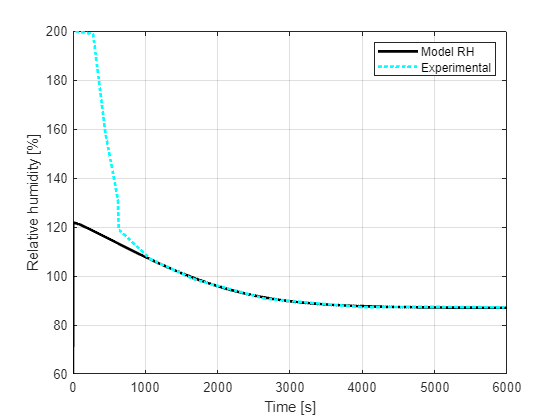

figure(1),plot(tSimula, RH5*100,'-k',t_RH_Sol,RH_Sol,':c', 'LineWidth',2), grid on, 
xlabel('Time [s]'), ylabel('Relative humidity [%]'), legend({'Model RH','Experimental'})

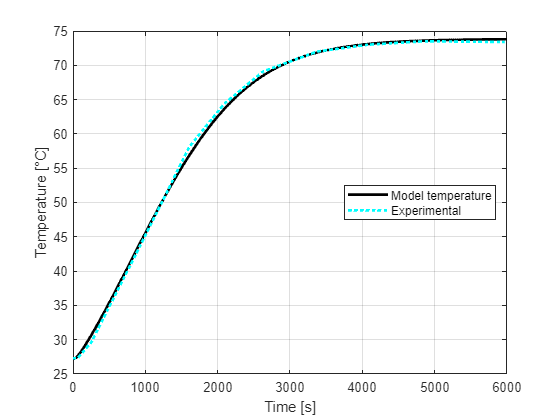


figure(2),plot(tSimula, T5-273,'-k',t_TAir_Sol,TAir_Sol,':c', 'LineWidth',2), grid on, 
xlabel('Time [s]'), ylabel('Temperature [°C]'), legend({'Model temperature','Experimental'},'Location','east')

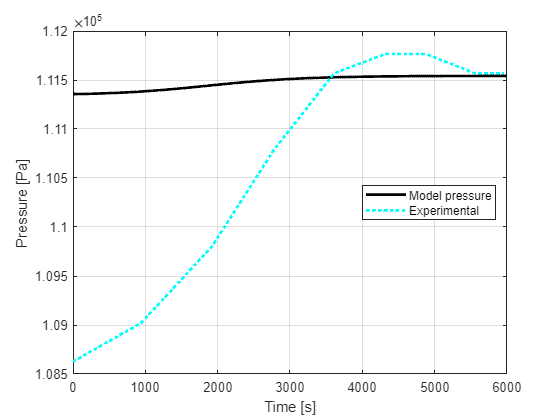

figure(3),plot(tSimula, P5,'-k',t_P5_Sol,P5_Sol,':c', 'LineWidth',2), grid on, 
xlabel('Time [s]'), ylabel('Pressure [Pa]'), legend({'Model pressure','Experimental'},'Location','east')